# 使用小波散射和LSTM的ECG信号分类

本示例说明如何使用小波时间散射和LSTM对人心电图（ECG）信号进行分类。 我们将训练一个长期短期记忆网络来识别以下心律：*正常窦性心律（NSR），心律不齐（ARR）或充血性心力衰竭（CHF）*。

clear
close all
clc

## I. 加载和预处理数据

数据是162个采样信号，以128Hz的频率（Fs）采样。数据下载链接：[`https://github.com/mathworks/physionet_ECG_data/`](https://github.com/mathworks/physionet_ECG_data/) 

load(fullfile(pwd, "ECGData.mat"))
Fs = 128;

这些信号分为三类：

unique(ECGData.Labels)

ans = 3×1 cell 数组
    {'ARR'}
    {'CHF'}
    {'NSR'}


其中ARR是指心律异常（心律失常）的信号，CHF是指充血性心力衰竭，NSR是指心律正常（正常窦性心律）

让我们看看其中一些信号是什么样的。

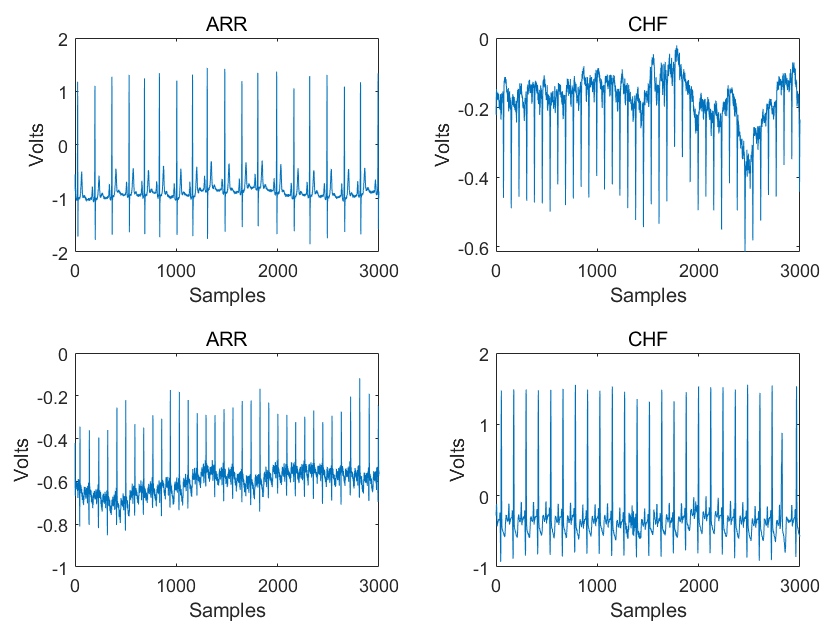

M = size(ECGData.Data, 1);
idxsel = randperm(M, 4);
tiledlayout(2, 2, "Padding", "compact")

for numplot = 1:4
    nexttile
    plot(ECGData.Data(idxsel(numplot),1:3000))
    ylabel('Volts')
    xlabel('Samples')
    title(string(ECGData.Labels(idxsel(numplot))))
end

这些信号可以观察到什么？ 从这些信号中我们可以预测哪些挑战？

## II. 使用小波散射自动特征提取

小波散射是一种可用于自动提取低方差，紧凑特征的技术，该方法可以最大程度地减少类内的差异，同时保留各个类之间的可区分性。

我们可以提供这些功能，而不是将原始表示提供给LSTM，以便网络可以快速学习模式并随后对信号进行分类。

sampleSig = ECGData.Data(1,:);
sf = waveletScattering('SignalLength',numel(sampleSig),'SamplingFrequency',Fs)

sf =   waveletScattering - 属性:

          SignalLength: 65536
       InvarianceScale: 256
        QualityFactors: [8 1]
              Boundary: "periodic"
     SamplingFrequency: 128
             Precision: "double"
    OversamplingFactor: 0


feat = featureMatrix(sf,sampleSig);

`变量`` feat `包含从信号中自动提取的特征。 在此示例中，我们使用2层网络提取所有要素。

whos sampleSig

  Name           Size                Bytes  Class     Attributes

  sampleSig      1x65536            524288  double              



whos feat

  Name        Size            Bytes  Class     Attributes

  feat      499x8             31936  double              



***与原始信号的长度相比，特征尺寸减少了95％***

### 可视化提取的特征 

我们可以独立检查来自每一层的特征

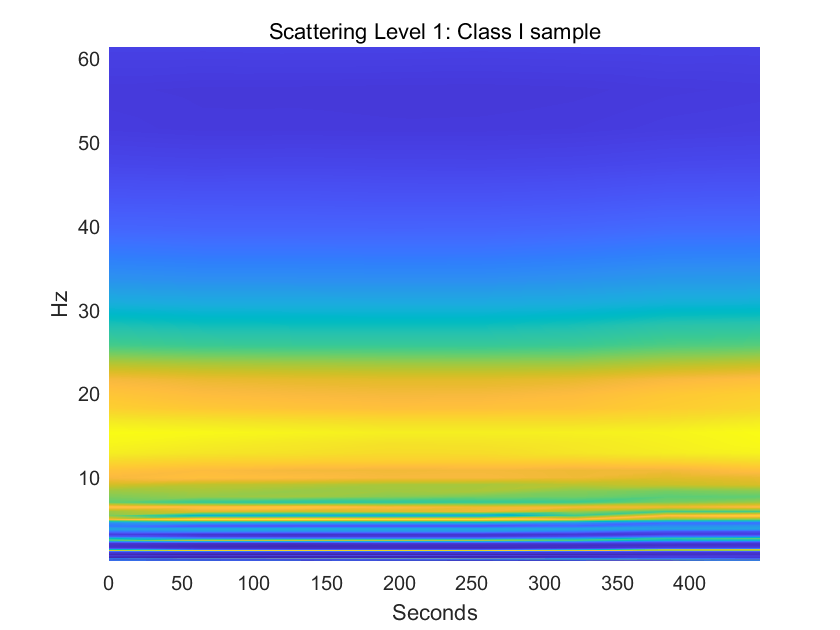

lev = 1;
[S1,U1] = scatteringTransform(sf,ECGData.Data(find(ECGData.Labels=="ARR",1),:));
[S2,U2] = scatteringTransform(sf,ECGData.Data(find(ECGData.Labels=="NSR",1),:));

scattergram(sf,S1,'FilterBank',lev);
title(sprintf('Scattering Level %d: Class I sample',lev));

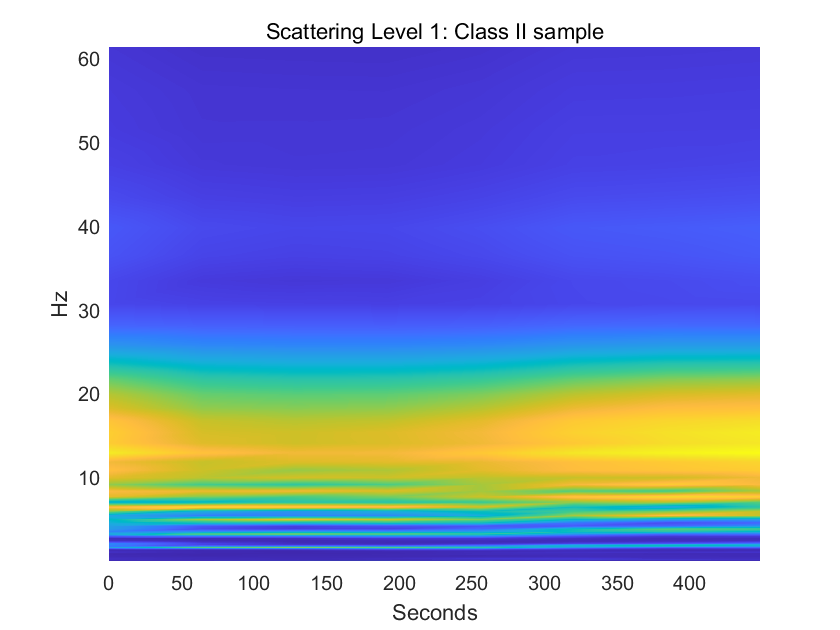

scattergram(sf,S2,'FilterBank',lev);
title(sprintf('Scattering Level %d: Class II sample',lev));

注意：上面显示的只是一种可视化提取了哪些特征的方法。 为每个信号提取一个499x8特征矩阵。 

### **提取训练和测试集中所有信号的特征**

让我们将数据集随机划分为训练数据集和测试数据集。

%load(fullfile(pwd, "data", "PartitionedData.mat"))
idxRandomized = randperm(M);
trainSize = 113;
testSize = M-trainSize;
trainData = zeros(trainSize, size(ECGData.Data,2));
trainLabels = cell(trainSize,1);
testData = zeros(testSize, size(ECGData.Data,2));
testLabels = cell(testSize,1);

for i=1:M
    if i <= trainSize
        trainData(i,:) = ECGData.Data(idxRandomized(i),:);
        trainLabels(i,1) = ECGData.Labels(idxRandomized(i));
    else
        testData(i-trainSize,:) = ECGData.Data(idxRandomized(i),:);
        testLabels(i-trainSize,1) = ECGData.Labels(idxRandomized(i));
    end
    
end

使用我们现有的小波散射变换，为训练和测试数据集计算散射特征。


scat_features_train = cell(trainSize,1);
scat_features_test = cell(testSize,1);

parfor itr = 1:113   %113 Training Records
    tmp = featureMatrix(sf,trainData(itr,:));
    scat_features_train{itr,1} =tmp;
end

parfor ttr = 1:49    % 49 Test Records
    tmp = featureMatrix(sf,testData(ttr,:));
    scat_features_test{ttr,1} =tmp;
end

## III. 利用散射特征训练LSTM

现在让我们建立一个非常简单的LSTM网络进行训练。

[inputSize,~] = size(scat_features_train{1});

YTrain = categorical(trainLabels);

numHiddenUnits = 100;
numClasses = numel(unique(YTrain));
maxEpochs = 125;
miniBatchSize = 1000;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

并建立一些通用的训练选项。

options = trainingOptions('adam', ...
    'InitialLearnRate',0.01,...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','shortest', ...
    'Shuffle','never',...
    'Plots','training-progress');

现在我们准备训练或者导入已经训练好的网络。

if true
    netScat = trainNetwork(scat_features_train,YTrain,layers,options);
else
    load(fullfile(pwd, "data", "netScat.mat"))
end

### **评估LSTM模型 **

现在我们可以测试我们训练好的模型：

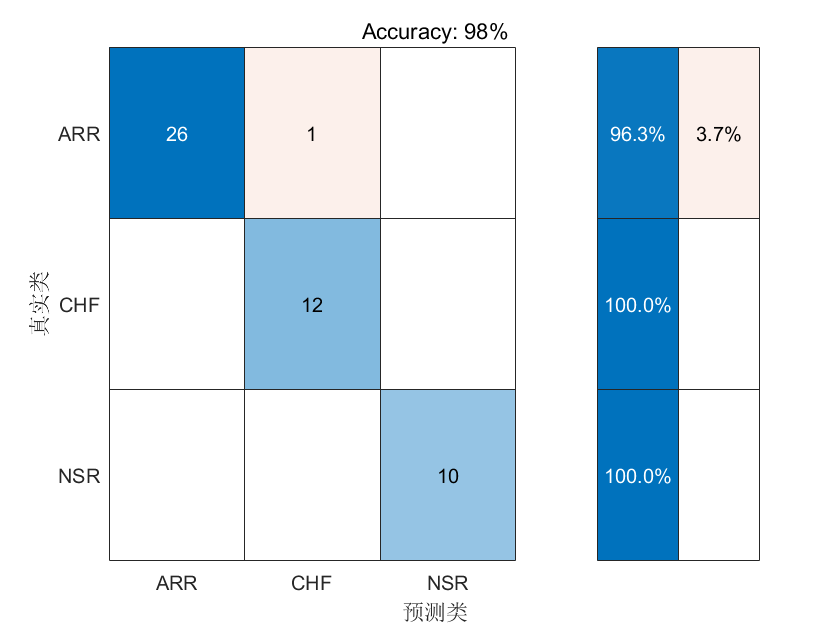

YTest = categorical(testLabels);

YPred = classify(netScat,scat_features_test, 'MiniBatchSize',miniBatchSize, 'SequenceLength','shortest');
accuracy = round((sum(YPred == YTest)./numel(YTest))*100);

confusionchart(YTest, YPred, "RowSummary", "row-normalized");
title("Accuracy: " + accuracy + "%")

### 提高分类准确度

如果您对结果不满意，则可以对散射滤波器组中的一个可选参数进行微调，以获得所需的结果。 invariance scale 的默认值是信号长度的一半（以样本为单位）。

您始终可以扫描 invariance scale 并使用贝叶斯优化来找出LSTM网络的超参数的正确组合。 

## 总结

本示例使用小波时间散射和LSTM将ECG波形分类为三个诊断类别之一。 小波散射被证明是功能强大的特征提取器，它只需要一组最少用户指定的参数即可产生一组可靠的分类特征。

*Copyright 2020 The MathWorks, Inc.*